**INDEX**

- **Plotting Vectors**

- **Plotting an axis/line parallel to an axis**

- **Plotting Matrices**

- **Hold ON/OFF**

- **axis tight**

- **xlim(), ylim()**

- **Line Design**

- **Line Markers (Marker Designs, MarkerEdgeColor, MarkerFaceColor)**

- **Line Colors**

- **Additional Line Specifications**

- **Plot Annotation (***title(), xlabel(), ylabel(), legend()*** functions)**

- **fplot() **function

- **fimplicit() **function

# **Plotting Vectors**

When we plot a single vector by itself, MATLAB uses the **values of the elements** of the vector as the ***y-axis***** data** and sets the ***x-axis***** data** to their **indices**.

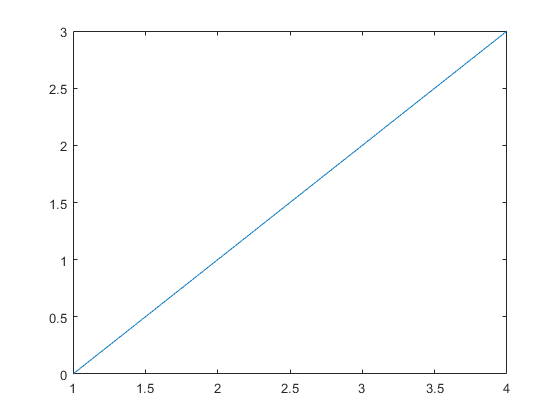

clear; 
clc;
plot([0, 1, 2, 3])

NOTE : It is important to keep in mind that when plotting one vector against another using *plot(v1, v2), *the first vector is kept on ***x-axis*** and the second vector is kept on the ***y-axis***.

# **Plotting an axis/Line parallel to an axis**

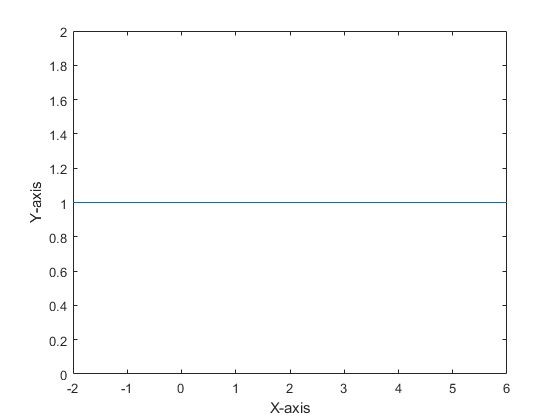

% plot([x_lower, x_upper], [y_value, y_value])
plot([-2 6], [1 1]) %plotting y = 1 (line parallel to x-axis) from x = -2 to x = 6
xlabel("X-axis")
ylabel("Y-axis")

This is useful in cases where we need to plot an axis/line parallel to an axis. For example, when we need to plot the axis of rotation of a solid of revolution.

# **Plotting Matrices**

When plotting a matrix, it's columns are taken as ***column vectors*** and plotted 1 by 1. This is useful when different formating is not needed for each of the curves, and the curves have to be plotted on the same axes.

matrix = randi([0, 10], 5, 3)

matrix =      8     1     1
     4     1     9
    10     9     6
     2     6     3
     2     6     5


positions = 1:5;
plot(positions, matrix)

**NOTE : **Observe that the **columns** of the matrix are plotted against the row vector *'positions'*. This is because the length of the column of the matrix, line up with the length of the row vector *'positions'*. If in case the length of the rows lined up with the length of the row vector *'positions'*.

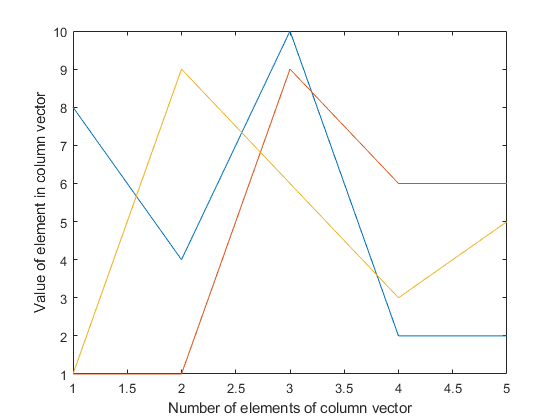

ylabel("Value of element in column vector")
xlabel("Number of elements of column vector")

# **Hold ON/OFF**

To plot one line on top of another, use the `hold on` command to hold the previous plot while you add another line. Example :

`plot(x1,y1)`

`hold on`

`plot(x2,y2)`

While the hold state is on, plots will continue to go on the same axes. To return to the default plot behavior, where each plot gets its own axes, enter `hold off`

# `axis tight`

`This function is used to constrict the graph to the plotted data points only and no excess unplotted data points are shown.`

# `xlim() ``and`` ylim()`

`Type these functions after the plot() function, as they are used to zoom in or out and are an afterthought of plotting the graph.`

`xlim([xmin xmax])`

`This function is used to zoom in or out on the ``x-axis`` of the graph plotted`

`ylim([xmin ymax])`

`This function is used to zoom in or out on the ``y-axis`` of the graph plotted`

# **Line Designs**

Most line plots display a solid line by default, but we can customize the line style. 

**Example : **

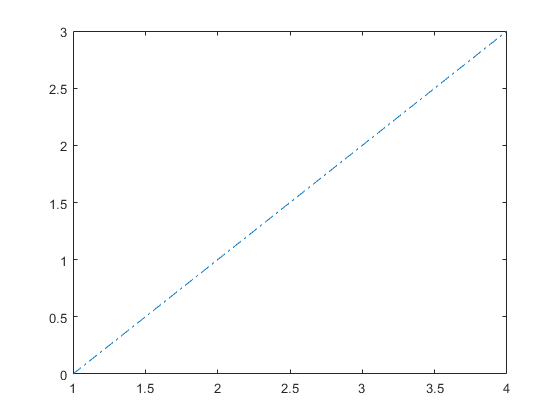

plot([0 1 2 3],'-.')

% This command will plot the elements of the vector on the y-axis
% and their indices on the x-axis

**Line Style            Description            Resulting Line**

`  '-'           `Solid line                 

`  '--'         `Dashed line               

`  ':'          `Dotted line                

`  '-.'       `Dash-dotted line           

# **Line Markers**

We can specify a marker symbol in addition to the line style. The markers appear at the data points in the chart. Some common markers are 'o', '`.`', 'x', '*', '+'.

For example:

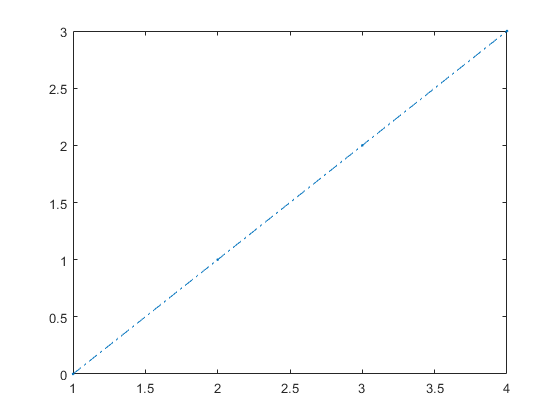

plot([0,1,2,3],".-.") %The first dot is the line marker, the subsequent dash-and-dot is the line style

 We can also specify the markers, **without any line style**, which will result in *only the markers being shown*.

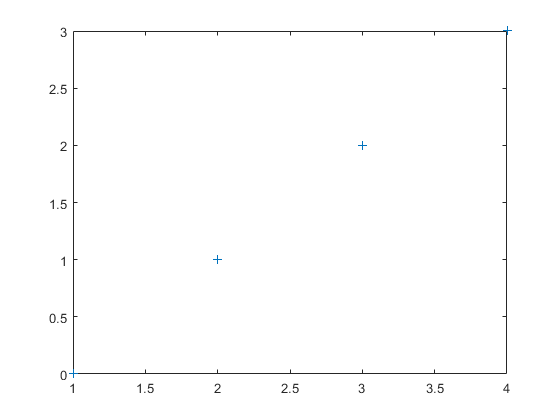

plot([0,1,2,3], "+")

# 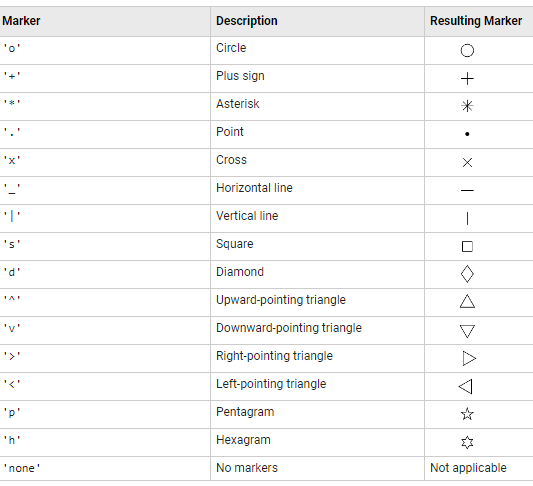

# **MarkerEdgeColor**

This parameter specifies the color for the edge lines for markers.

# **MarkerFaceColor**

This parameter specifies the color for the filling of filled markers.

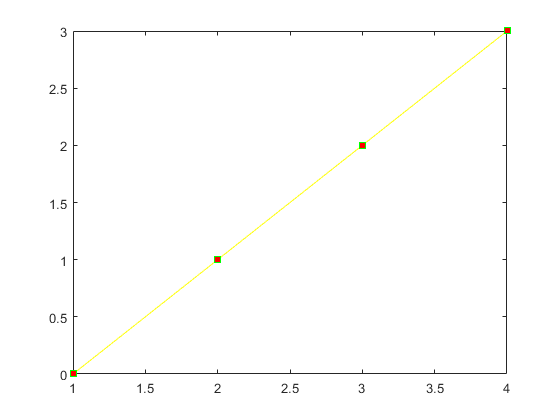

plot([0,1,2,3],"ys-","MarkerEdgeColor","g","MarkerFaceColor","r")

# **Line Colors**

                                        **                                       Color Name        Short Name**

                                        `                      'red'          'r'`

                                        `                     'green'         'g'`

                                        `                     'blue'          'b'  `

                                                                                  `'cyan'          'c'`

                                                                                  `'magenta'       'm' `

                                                                                  `'yellow'        'y'`

                                                                                   `'black'        'k'`

                                                                                  `'white'         'w'`

# **Additional Line Specifications**

**LineWidth ***(default = 0.5)*

Line width is  specified as a positive value in points. If the line has markers, then the **line width also affects the marker edges**.

The line width cannot be thinner than the width of a pixel. If you set the line width to a value that is less than the width of a pixel on your system, the line displays as one pixel wide. Example: 

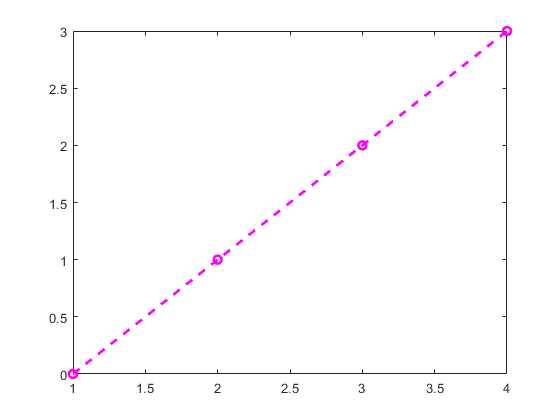

plot([0, 1, 2, 3], "mo--", "LineWidth", 2)

HISTOGRAMS

# **Plot Annotation**

Labels can be added to plots using plot annotation functions.

v1 = [9 4 3 10];
v2 = [2 5 6 9];
plot(v1, "o-")
hold on
plot(v2, "h-")
hold off

**title() function**

This function is used to add a title to a graph. For example:

title("Plot of vectors 'v1' AND 'v2'")

**ylabel() function**

This function is used to add a label for the data being represented on the ***y-axis.***

ylabel("Value of element of vector")

**xlabel() function**

This function is used to add a label for the data being represented on the ***x-axis.***

xlabel("Index of vector")

**NOTE : **We can use a variable's value in plot annotations by *concatenating* a string with a variable.

# **legend(***<name 1>[, <name 2>...]***) function**

A Legend can be added to our plot using *legend()* function. Simply write the names of the curves you have plotted, in the sequence you have plotted them, separated by commas. 

%legend("Vector 'v1", "Vector 'v2")

**NOTE : **It is also possible to store the names of the graphs in a **cell array** and pass that as a whole into the *legend()* function.

cellArray = [{"Vector 'v1'"}, {"Vector 'v2'"}]

cellArray = 1×2 cell array
    {["Vector 'v1'"]}    {["Vector 'v2'"]}


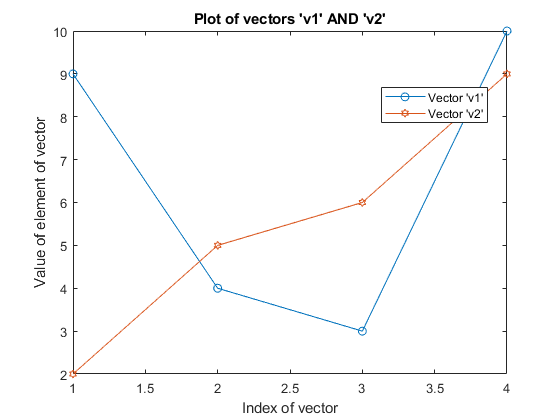

legend(cellArray, "Location", "Best") %We have specified location of the legend to be taken as the best possible

# ***fplot(****<explicit function>, [lower limit for plotting, upper limit for plotting]****)***

*fplot()* simplifies the process of plotting mathematical functions. 

Instead of obtaining datapoints(using *linspace()*, etc) and the value of the function at those datapoints, and then using *plot() *to plot both the vectors obtained :  ***[x*** and ***f(x)], *****we can directly use***** fplot().***

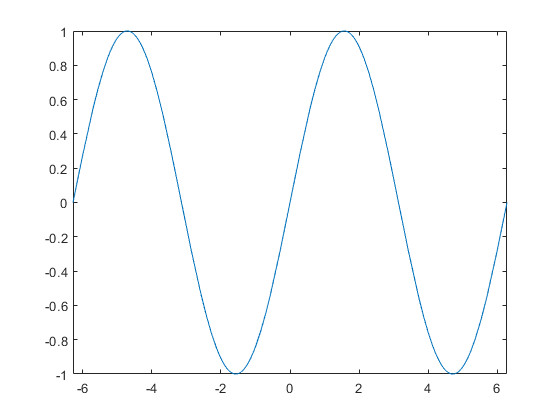

syms x
f(x) = sin(x);
fplot(f(x), [-2*pi, 2*pi]) % MAKE SURE TO ENTER A VECTOR CONTAINING THE UPPER AND LOWER LIMIT

# ***fimplicit(****<implicit equation/ function>, [lower limit for plotting, upper limit for plotting]****)***

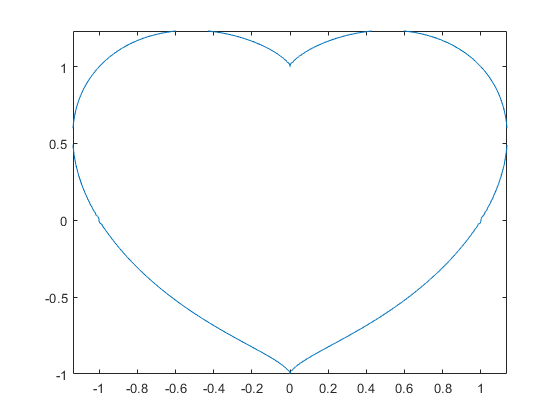

syms x y
fimplicit((x^2 + y^2 - 1) ^ 3 == x^2 * y^3)

This is an implicit **equation**, NOT a **function** because one value of 'x' is mapped to 2 values of 'y' at certain points

which goes against the definition of what a function is. See [42 - The implicit function theorem - YouTube](https://www.youtube.com/watch?v=bk9IKHS5KbY) for details on implicit fn./eqn.

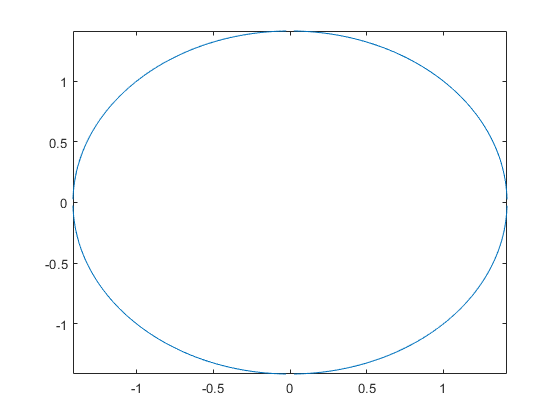

fimplicit(x^2 + y^2 == 2) %implicit equation. NOT function